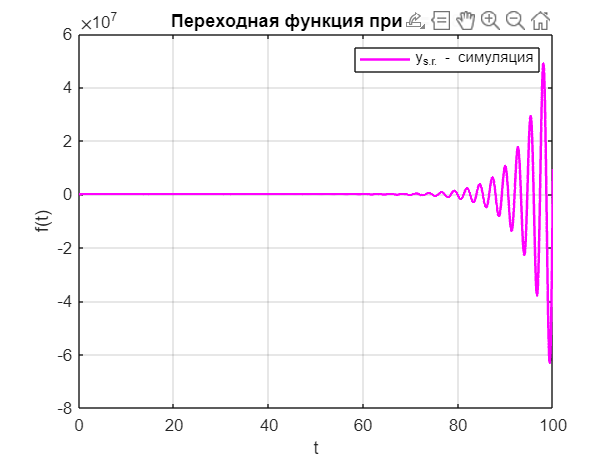

syms s;
open_system('task_3_2');
set_param('task_3_2/y', 'VariableName', 'y')

out = sim('task_3_2');
%{
[n1, d1] = deal(2*s+9, s^2+s+9);
[n2, d2] = deal(10*s^2-10*s+13, 10*s^3+37*s+25);
[eq, num, dem] = deal(2, n2,d2);
K=1;
%[mag,phase,wout] = bode(num, dem)
%F = tf('s'); sys = exp(-tau*s)*num/dem 
tau=0.3;
n_coeffs = sym2poly(num);
d_coeffs =  sym2poly(dem);
%sys = exp(-tau*s)*num/dem 

sys_i = tf(n_coeffs, d_coeffs, 'OutputDelay', tau)

impulse(sys_i, 'm')
legend('y_{i.r.} - симуляция')
title('Весовая функция при = 6.')
grid()
ylabel("f(t)")
xlabel('t')
%xlim([0 5])
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 1.5);
hold off
%}


plot(out.y, 'm')
legend('y_{s.r.} - симуляция')
title('Переходная функция при r = 0.8')
grid()
ylabel("f(t)")
xlabel('t')
%xlim([0 5])
%ylim([0 15])
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 1.5);
hold off

%{
figure('Position', [1000 0 800 450])
ops = bodeoptions;
ops.Title.String = 'ЛАФЧХ'
ops.Title.FontSize = 15
ops.XLabel.FontSize = 12
ops.YLabel.FontSize = 12
%ops.FreqScale = 'Linear';
   
h = bodeplot(sys_i, 'c', ops)
grid on;
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2);
%}

%{
F = tf(n_coeffs, d_coeffs, 'InputDelay', tau);
nyquist(F);
title("Годограф Найквиста при r = 5")
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 1);
% s = tf('s');
% if eq==1
%     W = (s+7)/(s^2+2*s+10);
% else 
%     %W = (10*s^2-10*s+13)/(10*s^3+37*s+25)
%     W=(10*s^2-5*s-15)/(10*s^3+5*s^2+10*s+38)
% end
% sys = exp(-1*tau*s)*W;
%[n1, d1] = deal(s+7, s^2+2*s+10);
%[n2, d2] = deal(10*s^2-5*s-15, 10*s^3+5*s^2+10*s+38);
%[num, dem] = deal(nd(eq,:))

%{
clf reset;
figure('Position', [1000 0 800 450])
hold on
rectangle('Position',pos,'Curvature',[1 1] ,LineStyle='-')
%[re,im,wout] = nyquist(F);
nyquist(F)
title("Годограф Найквиста")
%// radius
r = 1;
%// center
c = [0 0];
pos = [c-r 2*r 2*r];

%viscircles(0,1,'Color',"red");
axis equal
hold off;
%}
%}


